fid=fopen('Comp_Nodes.txt');
tline = fgetl(fid);
tlines = cell(0,1);
while ischar(tline)
    tlines{end+1,1} = tline;
    tline = fgetl(fid);
end
fclose(fid);



ans =     10    10     9    10    11    11    11    11    11    10


ans =     17    16    16    16    16    14    14    15    14    11


ans =     17    18    18    17    16    15    13    12    13    10


ans =     16    15    15    15    15    15    14    15    15    14


ans =     21    20    20    18    17    18    17    17    18    18


ans =     27    27    27    29    30    31    32    33    32    33


ans =     43    42    42    43    43    43    44    43    42    39


ans =     31    30    29    29    30    30    30    32    33    29


ans =     28    28    29    29    29    28    29    28    27    26


ans =     40    40    39    40    40    42    44    46    47    44


ans =     29    29    30    32    33    33    32    33    32    30


ans =     22    22    23    23    22    22    22    23    25    22


ans =     87    87    86    86    87    88    90    90    91    88


ans =     74    74    75    77    77    78    79    80    81    80


ans =     99   100   100   101    99    97    97    97    97    94


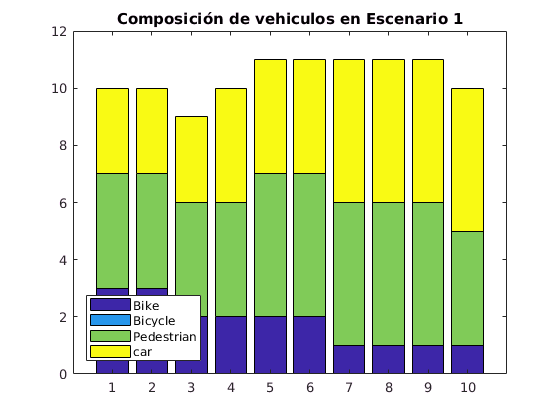

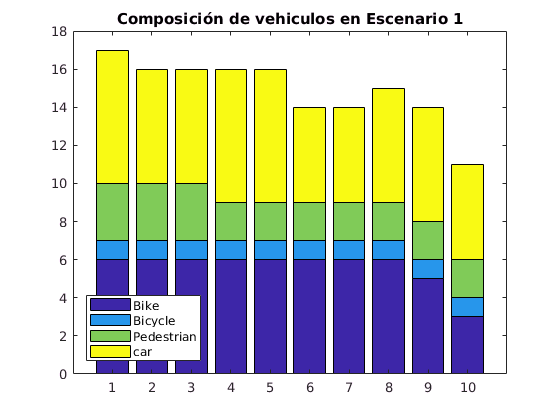

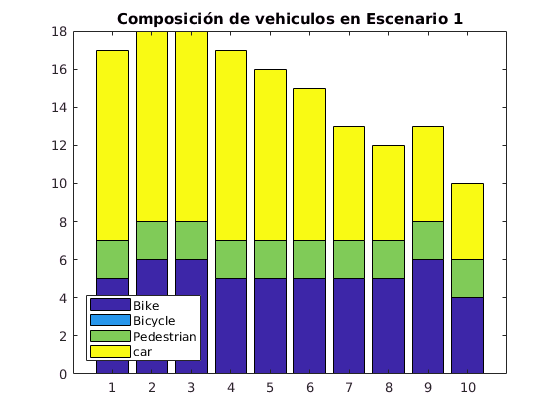

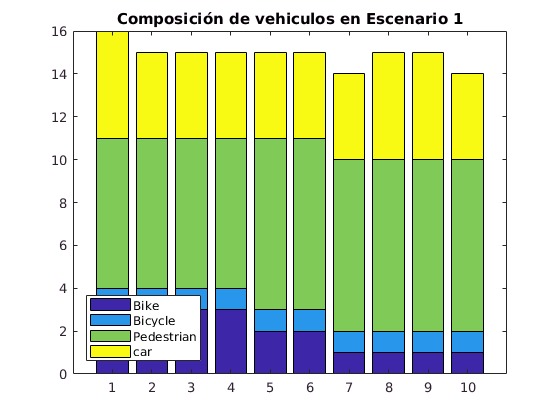

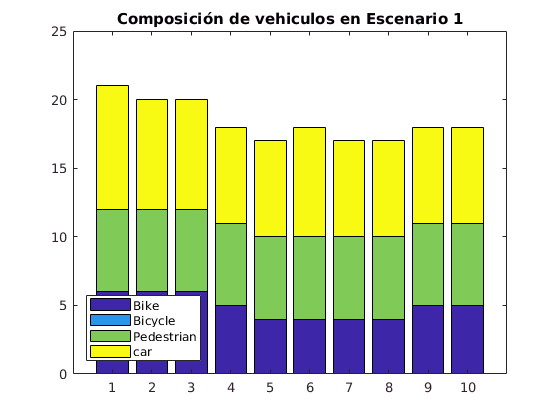

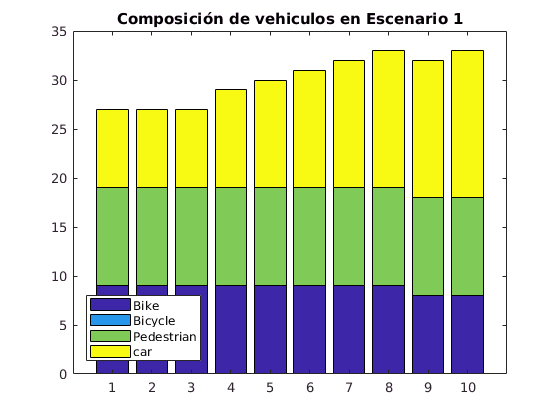

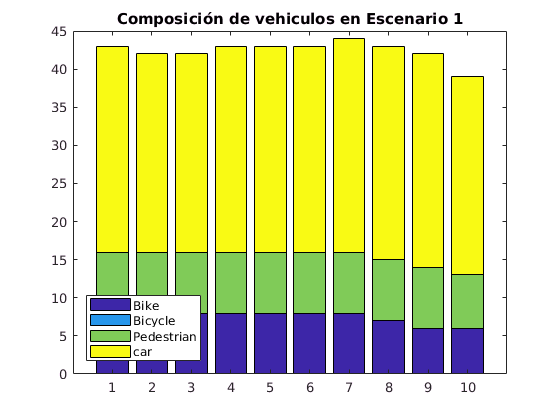

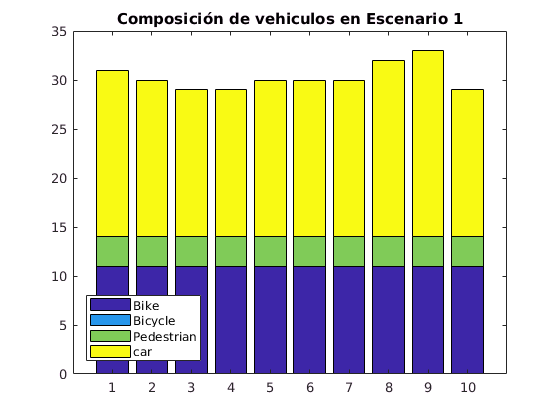

for j=1:3:(length(tlines)-3)

LD_Nodes = [str2num(tlines{j}) ; str2num(tlines{j+1}) ; str2num(tlines{j+2})]';
%DEN=20599s,22330s,22113s,23916s
ind2 = zeros(4,10);
ini_T = min(LD_Nodes(:,1));

for i=1:length(LD_Nodes)
    ini_n = LD_Nodes(i,1)-ini_T+1;
    fin_n = LD_Nodes(i,2)-ini_T;
    ind2(LD_Nodes(i,3),ini_n:fin_n)= ind2(LD_Nodes(i,3),ini_n:fin_n)+1;
  
end 

sum(ind2)

figure (j)
bar(ind2','stacked')
title('Composición de vehiculos en Escenario 1')
legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
xlim([0 11])

end